# Rapport TP 1 : Oscillateur à AOP

## 1) Oscillateur à pont de Wien

### 1. Bode

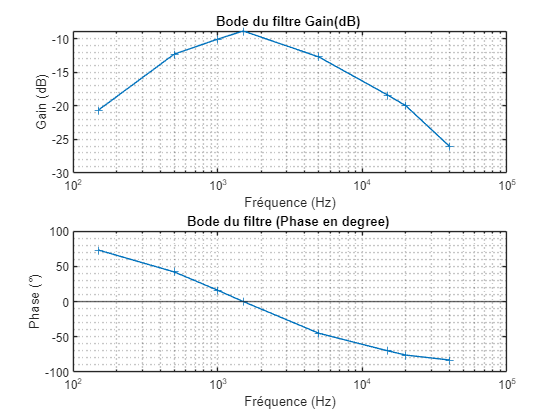

Ve = 1;
f =     [0.15 0.5 1 1.5 5 15 20 40]*1e3;
Vs = [93 242 313 360 231 120 100 50]*1e-3;
Phase = [-73 -42 -16 0 45 70 76 83].*-1;

G = 20*log10(abs(Vs));
Phi = angle(Vs./Ve)*180/pi;

figure()
subplot(2,1,1)
semilogx(f,G,'+-')
grid("minor")
title("Bode du filtre Gain(dB) ");xlabel("Fréquence (Hz)");ylabel("Gain (dB)")
subplot(2,1,2)
semilogx(f,Phase,'+-');
yline(0);
title("Bode du filtre (Phase en degree) ");xlabel("Fréquence (Hz)");ylabel("Phase (°)")
grid("minor")

$f_0 =\frac{1}{2\pi \times R\times C}=\frac{1}{2\pi \times 15e^3 \times 6\ldotp 8e^{-9} }=1500\;\textrm{Hz}$.

En théorie, la frquence de coupure du montage est égale à 1.5kHz ; en pratique, nous relevons une phase nulle à 1.5kHz.

$G=20\times \log \left(\frac{V_{S_{\textrm{f0}} } }{V_E }\right)=20\times \log \left(\frac{360e^{-3} }{1}\right)=-8\ldotp 5\textrm{dB}$.

Le gain théorique de ce montage est $-9\ldotp 5\textrm{dB}$. Nous calculons $-8\ldotp 5\textrm{dB}$avec les valeurs expérimentales.

### **2. **Oscillation du montage

Pour générer une ondulation avec l'AOP, on veut que le filtre et le montage de l'AOP aient le même gain : un gain environ égal à 3. On se sert alors du potentiomètre pour régler le gain de l'amplificateur.

La fréquence d'oscillation du montage est également égale à 1.5kHz.

### 3. Petit Signal

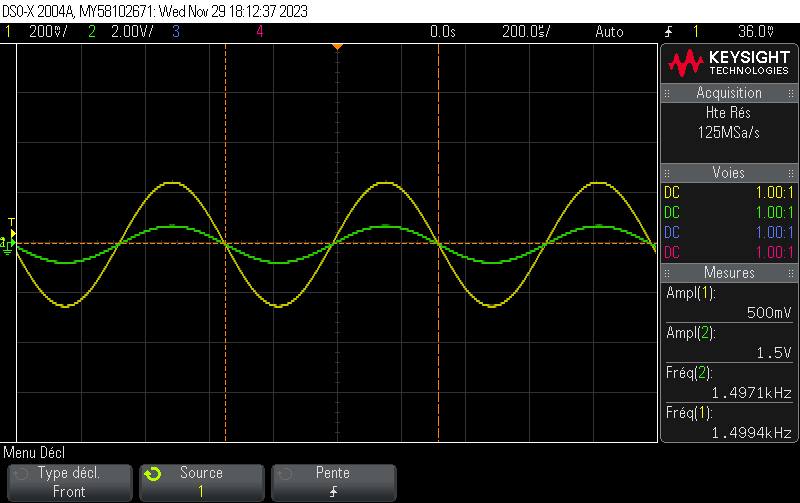

On débranche le filtre pour vérifier que le gain du montage amplificateur : on a bien un gain environ égal à 3 à une fréquence de 1.5kHz

## 2) Oscillateur à réseau de déphasage

### 1. Bode

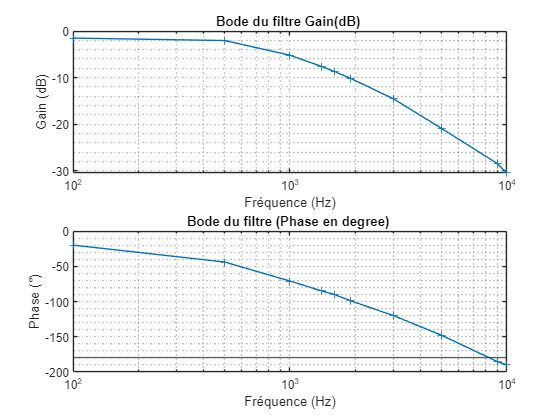

Ve = 1;
f = [0.1 0.5 1 1.4 1.6 1.9 3 5 9 10]*1e3;
Vs = [840 790 550 416 368 311 187 90 38 30]*1e-3;
Phase = [20 44 71 85 90 99 120 148 185 190].*-1;

G = 20*log10(abs(Vs));

figure()
subplot(2,1,1)
semilogx(f,G,'+-')
grid("minor")
title("Bode du filtre Gain(dB) ");xlabel("Fréquence (Hz)");ylabel("Gain (dB)")
subplot(2,1,2)
semilogx(f,Phase,'+-');
yline(-180);
title("Bode du filtre (Phase en degree) ");xlabel("Fréquence (Hz)");ylabel("Phase (°)")
grid("minor")

$f_0 =\frac{1}{2\pi }\sqrt{\frac{6}{{\left(R\times C\right)}^2 }}=\frac{1}{2\pi }\sqrt{\frac{6}{{\left(6\ldotp 8e^3 \times 6\ldotp 8e^{-9} \right)}^2 }}=8430\;\textrm{Hz}$. En théorie, la fréquence de coupure est égale à 8430 Hz, mais en pratique, nous relevons cette fréquence environ égale à 9000 Hz.

$G=20\times \log \left(\frac{V_{S_{\textrm{f0}} } }{V_E }\right)=20\times \log \left(\frac{38e^{-3} }{1}\right)=-28\ldotp 4$. Le gain pratique est égal à -28.4. En théorie, on devrait avoir un gain de -29.

### **2. **Oscillation du montage

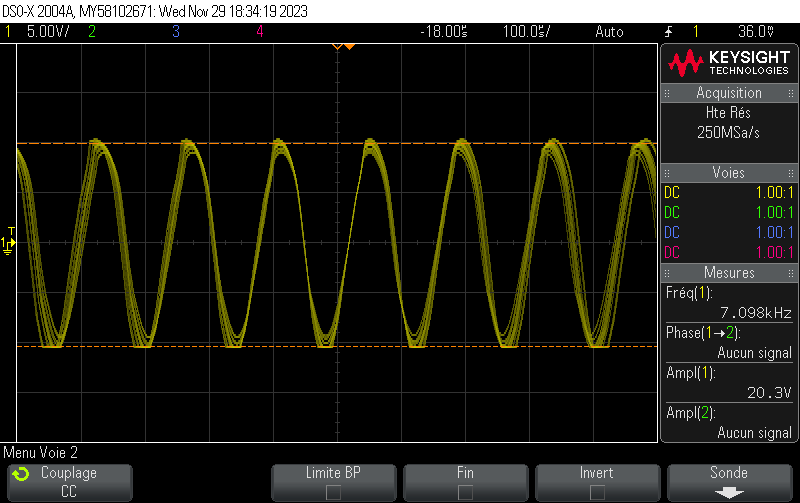

Une fois réglé, nous parvenons a faire osciller le montage à une fréquence environ égale à 7kHz. 

Cette erreur de précision s'explique par notre platine qui avait des problèmes liés à ses potentiomètres : nous devions appuyer sur ces derniers pour pouvoir observer l'oscillation.

### 3. Petit Signal

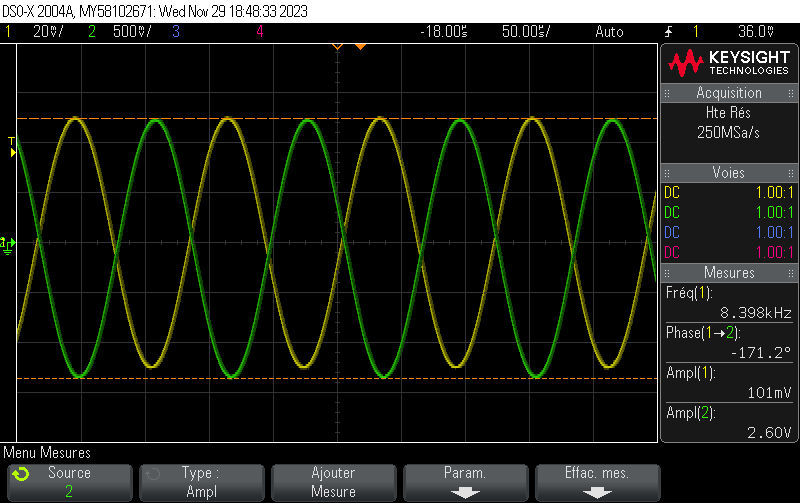

En montage petit signal (sans le filtre), le gain du montage amplificateurs est égal à 8.4kHz, avec une phase d'environ $\pi$. Ce gain s'explique par le montage en série de deux AOP amplificateur inverseur et non-inverseur qui créent un gain très élevé (dans notre cas, on a réglé les montages pour avoir un gain de 29, nous annuler le gain du filtre). Enfin, le déphasage de $\pi$ s'explique par le montage inverseur et non-inverseur en série.

## 3) Oscillateur double T

### 1. Bode

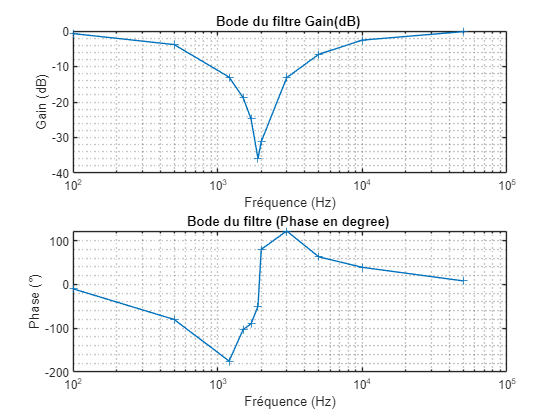

Ve = 0.5;
f = [0.1 0.5 1.2 1.5 1.7 1.9 2 3 5 10 50]*1e3;
Vs = [460 322 112 57.5 29 8 13.8 110 235 372 490]*1e-3;
Phase = [10 80 175 103 90 50 -80 -122 -63 -39 -8].*-1;

G = 20*log10(abs(Vs./Ve));
Phi = angle(Vs./Ve)*180/pi;

figure()
subplot(2,1,1)
semilogx(f,G,'+-')
grid("minor")
title("Bode du filtre Gain(dB) ");xlabel("Fréquence (Hz)");ylabel("Gain (dB)")
subplot(2,1,2)
semilogx(f,Phase,'+-');
title("Bode du filtre (Phase en degree) ");xlabel("Fréquence (Hz)");ylabel("Phase (°)")
grid("minor")

$f_0 =\frac{1}{2\pi \times r\times c}$ avec $r=\textrm{R1}=8\ldotp 2\;k\Omega$ et $c=\textrm{C1}=11\;\textrm{nF}$ $\Longrightarrow f_0 =\frac{1}{2\pi \times r\times c}=\frac{1}{2\pi \times 8\ldotp 2e^3 \times 11e^{-9} }=1764\;\textrm{Hz}$. 

La fréquence de coupure théorique est égale à 1764 Hz. En pratique, nous mesurons environ 1887 Hz.

### 2. Le gain

$G=20\times \log \left(\frac{V_{S_{\textrm{f0}} } }{V_E }\right)=20\times \log \left(\frac{8e^{-3} }{500e^{-3} }\right)=-35\ldotp 9$.

Théoriquement, le gain est égal à 

En pratique, nous calculons -36dB environ.

### 3. Oscillation du montage

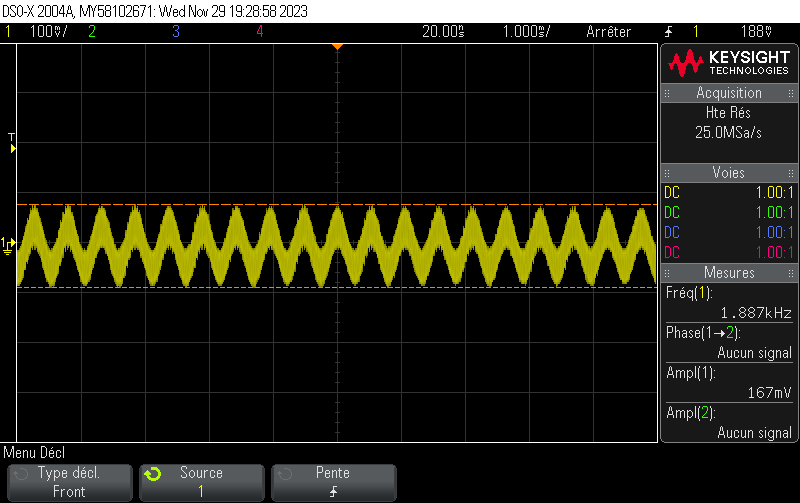

Quand nous parvenons à faire osciller le montage, on a une fréquence d'oscillation égale à 1887Hz.

### 4. Petit Signal

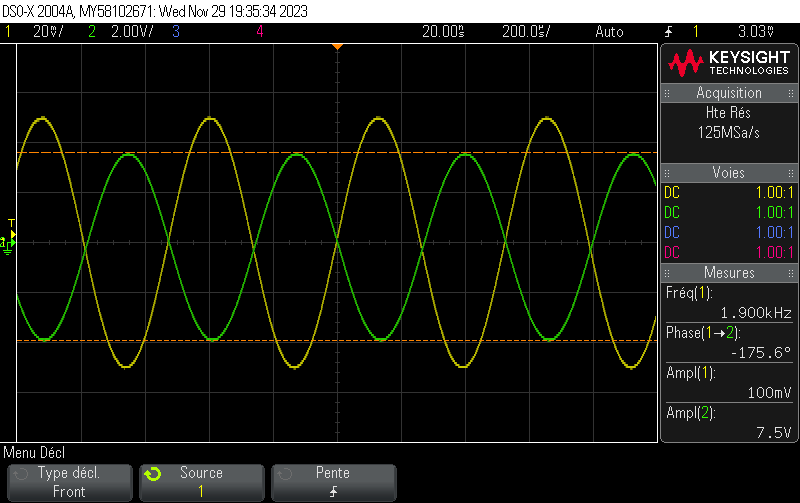

Nous débranchons le filtre et connectons le GBF pour générer une fréquence égale à la fréquence de coupure et une faible amplitude : nous mesurons un gain égal à 75.

## 4) Contrôle automatique de Gain

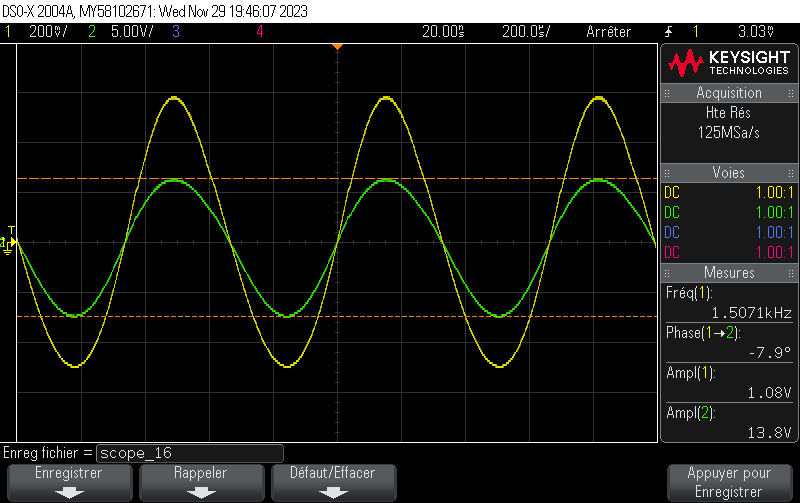

La fréquence de coupure du montage avec le contrôleur de gain est égal à 1.5kHz, avec un gain environ égal à 13.

Ces valeurs sont identiques aux valeurs théoriques calculées : en effet, le montage réalisé est celui de la partie 1 (avec le pont de Wien). Ce dernier avait une fréquence d'ondulation égale à 1500Hz.